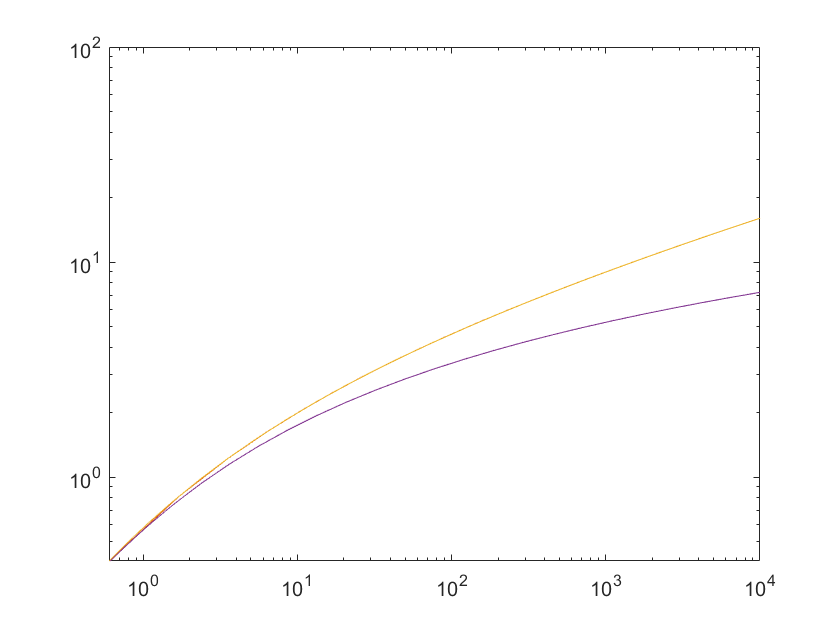

H = 1;
% Ks = {-40, -4, -2, -1, 1, 2, 4, 40};
Ks = {-4};
for ki = 1:length(Ks)
    K = Ks{ki};
    syms x_eq;
    x_eq_f = x_eq / (H * (1 - x_eq / K) ^ K);
    x_eq_f_fp = fplot(x_eq_f);
    x_eq_f_fp.Visible = 0;
    hold on;
    axis([0 10000 0 100]);
    plot(x_eq_f_fp.YData, x_eq_f_fp.XData);
    set(gca, 'XScale', 'log');
    set(gca, 'YScale', 'log');
    syms y_eq;
    y_eq_f = finverse(y_eq / (H * (1 - y_eq / K) ^ K), y_eq);
    fplot(y_eq_f);
    syms x;
    fplot(lambertw(x));
end
hold off;